# Lecture 4 Transfer function and image filtering

In the previous lecture, we showed that the linear shift invariant (LSI) system's eigenfunctions are exponential functions. The signal can be conveniently decomposed on the eigenspace of the LSI system with the Fourier transform, which introduces the concept of spectral analysis. We also showed several properties of the Fourier transform, particulary the convolution-multiplication property. In this lecture, we will revisit the image filtering concepts and connect the dots. Specifically, this lecture will introduce system transfer function, extending to optical transfer function (OTF) and modulation transfer function (MTF) in the future chapters, which are the key concepts in optical imaging system characterization.

## 1. Transfer function of linear shift invariant system

### 1.1 Eigenfunction revisited

As discussed in the previous lecture, an eigenfunction of a system is a non-zero function that, when used as input signal, results in the output of itself scaled by a constant factor. For LSI system, the exponential function $e^{i\omega \;t}$is an eigenfunction, shown in ILL. 1.1.

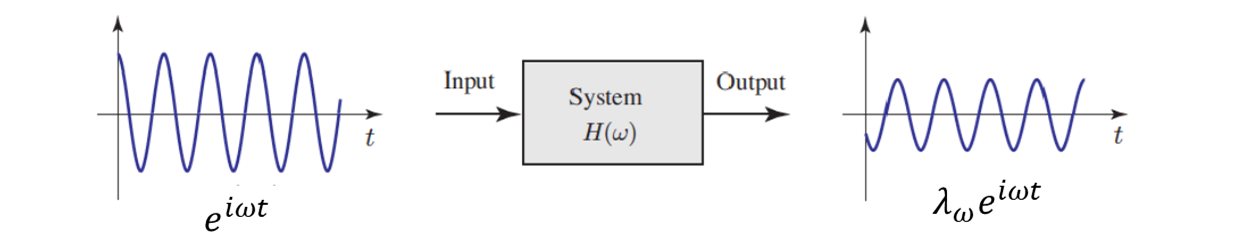

**ILL. 1.1*** Illustration of the expoential function (the eigenfunction) input will result in exponent function output for LSI system.*

***Example 1.1***

Demonstration of LSI system gain by feeding in an exponent function.

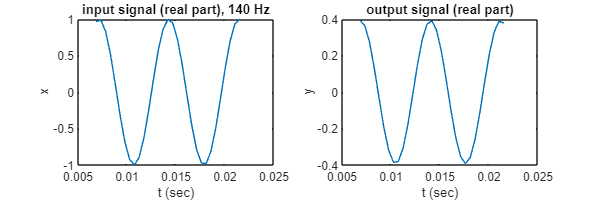

nt = 1024; % number of time points
t_max = 0.5;% time span [Unit: sec]
t = linspace(0,t_max,nt);
dt = t(2)-t(1);
freq = 140; % frequency [Unit: Hz]
omega = 2*pi*freq; % angular frequency [Unit: rad/sec]
n_prd = ceil(1/freq/dt); % number of pixels per period. 
x = exp(1i.*omega*t);% input
kernel = ones(1,10)./10; % 10 tap averaging filter.
y = conv(x,kernel,"same"); % output
figure;
subplot(121)
plot(t(n_prd:3*n_prd),real(x(n_prd:3*n_prd)));% show the 1st to 3rd period
xlabel('t (sec)'),ylabel('x');
title(['input signal (real part), ',num2str(freq),' Hz'])
subplot(122)
plot(t(n_prd:3*n_prd),real(y(n_prd:3*n_prd)));
xlabel('t (sec)'),ylabel('y');
title('output signal (real part)')
set(gcf,'Position',[100 100 600 200]);

When you slide the frequency of the input, you can see that the amplitude and the phase of the output changes. When the freqeuncy hits ~ 200 Hz, the amplitude is only about 2% of the input. But the frequency of the ouput is always the same as the input. 

***Note***: It is not correct to say that harmonic functions (i.e., sine and cosine) are eigenfunctions of LSI systems. If we have input $x\left(t\right)=\cos \left(\omega t\right)$, we expect a general form of output to be


$$x\left(t\right)\overset{\textrm{LSI}}{\longrightarrow} y\left(t\right)=A_{\omega } \;\cos \left(\omega t+\phi_{\omega } \;\right)$$


The output not only changes the amplitude, but also differs by a phase shift. The output still has the same shape, but it does not has the form $\lambda_{\omega \;} x\left(t\right)$. Therefore the harmonic function is not an eigenfunction. However, if you add an imaginary part with $\frac{\pi }{2}$ phase shift, then you construct the exponent function $x_e \left(t\right)=\exp \left(i\omega t\right)$. The shift is in the phase part of complex factor.

$x_e \left(t\right)\overset{\textrm{LSI}}{\longrightarrow} y_e \left(t\right)=A_{\omega \;} \exp \left(i\phi_{\omega } \right)\;\exp \left(i\omega t\right)$,

in which $\lambda_{\omega } =$$A_{\omega \;} \exp \left(i\phi_{\omega } \right)$ is the eigenvalue.

### 1.2 Transfer fucntion

As we can see in the precious section, this complex 'factor', $\lambda_{\omega }$, can be treated as a function of frequency. We give it the formal name ***transfer function***:$H\left(\omega \right)$. You may have guessed why we use $H\left(\omega \right)$ here. Remember that in Lecture 2, we concluded that any LSI system can be modeled as the input convolved with a kernel $h\left(t\right)$. The kernel uniquely determines the LSI system. The output 


$$g\left(t\right)=h\left(t\right)\otimes f\left(t\right)$$


The input and output can be expressed in the frequency domain:


$$g\left(t\right)=\int G\left(\omega \right)\phi_{\omega \;} \left(t\right)\textrm{dt},$$



$$f\left(t\right)=\int F\left(\omega \right)\phi_{\omega \;} \left(t\right)\textrm{dt},$$


where $F\left(\omega \right)$ and $G\left(\omega \right)$ are the Fourier transforms of $f\left(t\right)$ and $g\left(t\right)$, respectively. Since $\phi_{\omega \;} \left(t\right)$ is an eigenfunction of the system, 


$$\lambda_{\omega } \phi_{\omega \;} \left(t\right)=h\left(t\right)\otimes \phi_{\omega \;} \left(t\right)\ldotp$$


Therefore:


$$\begin{array}{l}
\int G\left(\omega \right)\phi_{\omega \;} \left(t\right)\textrm{dt}=h\left(t\right)\otimes \int F\left(\omega \right)\phi_{\omega \;} \left(t\right)\textrm{dt}\\
=\int F\left(\omega \right)\left\lbrack h\left(t\right)\otimes \phi_{\omega \;} \left(t\right)\right\rbrack \textrm{dt}=\int F\left(\omega \right)\lambda_{\omega } \phi_{\omega \;} \left(t\right)\textrm{dt}
\end{array}$$


$\Rightarrow G\left(\omega \right)=\lambda_{\omega } F\left(\omega \right)$.

According to the Fourier convolution property:$G\left(\omega \right)=H\left(\omega \right)F\left(\omega \right)$, where $H\left(\omega \right)$ is the Fourier transform of the kernel, i.e. $h\left(t\right)\overset{\textrm{FT}}{\longrightarrow} H\left(\omega \right)$. Then the eigenvalue of the system $\lambda_{\omega }$ is the Fourier transform of the kernel function. Kernel $h\left(t\right)$ is the inverse Fourier transform of $H\left(\omega \right)$, also called the point spread function (PSF) for 2D spatial coordinates.

It becomes clear that the signal passing through a LSI system is equivalent to a 'filtering' process: Consider the input signal as a superposition of all frequency components; the system enhances or supresses specific components determined by the transfer function $H\left(\omega \right)$. If $H\left(\omega \right)$ is 0, or some very small value at some $\omega$, the output will not have these freqeuncy components, essentially being filtered out from the input. By performing Fouier transform of the kernel, we can characterize the spectral response of a LSI system.

Examples of transfer functions of three common types of filter are shown in ILL. 1.2.

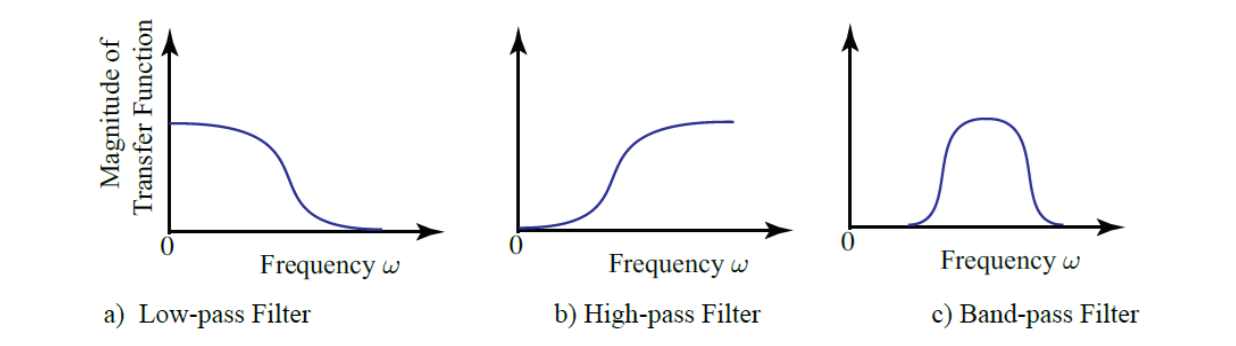

**ILL 1.2*** Transfer function of 1D low-pass, high-pass, and band-pass filters*

***Example 1.2 ***

1D Boxcar filter.

[`B`](https://www.mathworks.com/help/images/ref/padarray.html#d124e244047) `= padarray(`[`A`](https://www.mathworks.com/help/images/ref/padarray.html#d124e243781)`,`[`padsize`](https://www.mathworks.com/help/images/ref/padarray.html#d124e243831)`)` pads array `A` with an amount of padding in each dimension specified by `padsize`. 

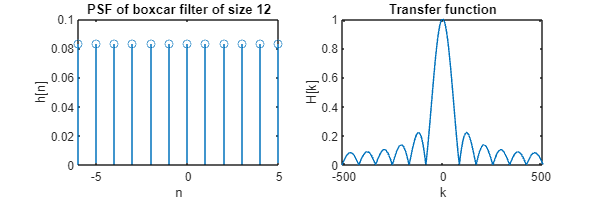

nt = 1024;
n_tap =12; % the size of boxcar filter
kernel = ones(1,n_tap)./n_tap; 
pad_size = round((nt-length(kernel))/2);
kernel_pad = padarray(kernel,[0,pad_size],'both');
H = fftshift(fft(fftshift(kernel_pad)));
figure;
subplot(121);
stem((round(-n_tap/2):round(n_tap/2)-1),kernel);
title(['PSF of boxcar filter of size ', num2str(n_tap)]);
xlabel('n'), ylabel('h[n]');
subplot(122);
plot((round(-nt/2):round(nt/2)-1),abs(H));
title('Transfer function');
xlabel('k'),ylabel('H[k]');
set(gcf,'Position',[100 100 600 200]);

The transfer function shows a low-pass filter behavior with some side bands.

***Example 1.3***

1D difference filter.

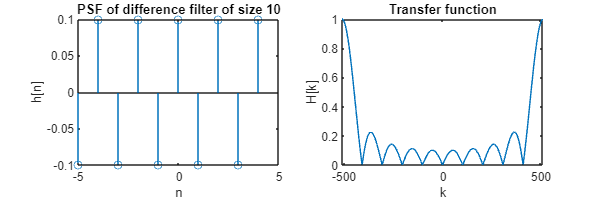

nt = 1024;
n_tap =10; % the size of difference filter
kernel = repmat([-1,1],[1,n_tap/2])./n_tap; 
pad_size = round((nt-length(kernel))/2);
kernel_pad = padarray(kernel,[0,pad_size],'both');
H = fftshift(fft(fftshift(kernel_pad)));
figure;
subplot(121);
stem((round(-n_tap/2):round(n_tap/2)-1),kernel);
title(['PSF of difference filter of size ', num2str(n_tap)]);
xlabel('n'), ylabel('h[n]');
subplot(122);
plot((round(-nt/2):round(nt/2)-1),abs(H));
title('Transfer function');
xlabel('k'),ylabel('H[k]');
set(gcf,'Position',[100 100 600 200]);

The transfer function shows a high-pass filter behavior with some side bands. Please adjust the length of the difference filter and observe the change of the passband.

### **1.3 Fast Fourier transform for convolution**

According to Fourier convolution theorem, instead of directly calculating the convoution in the time domain (red path in ILL. 1.3 ), we can carry out the calculation in the freqeuncy domain (blue path). It seems that the direct convolution is straightforward; however, if we consider the convolution of a PSF (kernel) of size $N$ and  input of size $N$, the number of steps for relative shifting is $2N-1$. At step $k$, the number of multiplication is $k$. The total number of multiplication will be $\sum_{k=1}^{2N-1} k=2N\left(N-1\right)$. The computational complexity is of order $O\left(N^{2\;} \right)$. 

However, if we use spectral domain multiplication. The fast Fourier transform's computational complexity is $O\left(N\log_2 N\right)$. The multiplication in the spectral domain requires $N$ multiplications. Though the calculation requires 3 FFT (blue arrow), the total computational complexity is still $O\left(N\log_2 N\right)$, which is lower than $O\left(N^{2\;} \right)$, particularly for large $N$.

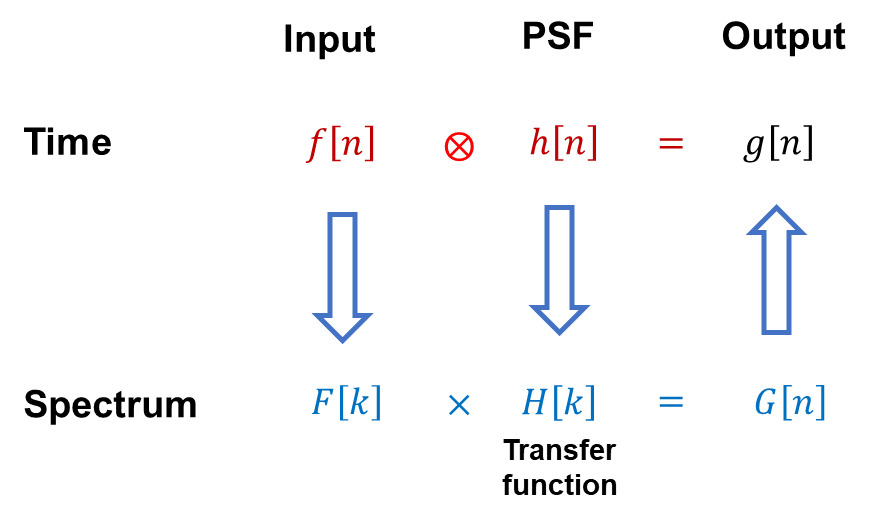

**ILL. 1.3*** Calculating convolution using Fourier convolution theorem.*

***Example 1.4 ***

Fast convolution using FFT

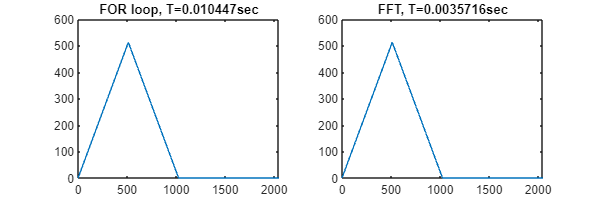

N = 1024;
f = zeros(1,N);
h = zeros(1,N);
w = 1:N/2; % width of rectangular function
f(w) = 1; % rectangular function as input
h(w) = 1; % rectangular function as kernel
g = zeros(1,2*N); % output

t0 = tic; % time the convolution
for ii = 1:N
    for jj = 1:N
        g(ii+jj) = g(ii+jj)+h(ii)*f(jj);
    end
end
del_t = toc(t0);

% matlab built-in convolution
g1=conv(h,f,'full'); 

% multiplication in frequency domain
h_f = padarray(h,[0,N],'post');
f_f = padarray(f,[0,N],'post');
t2 = tic;
g2 = ifft(fft(h_f).*fft(f_f));
del_t2 = toc(t2);
figure;
subplot(121)
plot(g)
title(['FOR loop, T=',num2str(del_t),'sec'])
subplot(122)
plot(abs(g2))
title(['FFT, T=',num2str(del_t2),'sec'])
set(gcf,'Position',[100 100 600 200]);

It is worth noting that using `for` loops is not efficient for interperative language such as MATLAB. However, it shows that convolution calculation in the freqeuncy domain is faster, especially when N is large and the two arrays are of comparible size. Please try the MATLAB built-in `conv` function, and check the time needed for excution.

## 2. Two-dimensional transfer function

As in the 1D case, the convolution relation corresponding to multiplication in the Fourier domain, i.e., $G\left(k_x ,k_y \right)=H\left(k_x ,k_y \right)F\left(k_x ,k_y \right)$, where $k_x ,k_y$ are the spatial frequency in x, y coordiates, respectively. $G\left(k_x ,k_y \right)$,$H\left(k_x ,k_y \right)$ and $F\left(k_x ,k_y \right)$ are the 2D Fourier transforms of output $g\left(x,y\right)$, PSF $h\left(x,y\right)$, and input $f\left(x,y\right)$, respectively.

Similar to the 1D transfer function we showed in the section before, low-pass, high-pass, and band-pass filter are the common types of filter. ILL. 2.1 shows some examples of the transfer functions of 2-D filters. ILL. 2.1 (a) and (b) shows isotropic filters whose transfer function is only a function of the radial coordinate, i.e. $H\left(\rho \right),\rho =\sqrt{\;k_x^2 +k_y^2 }$. With the additional dimension, the filtering can selectively filter the frequency components in a specific dimension, shown in ILL. 2.1 (c) and (d).

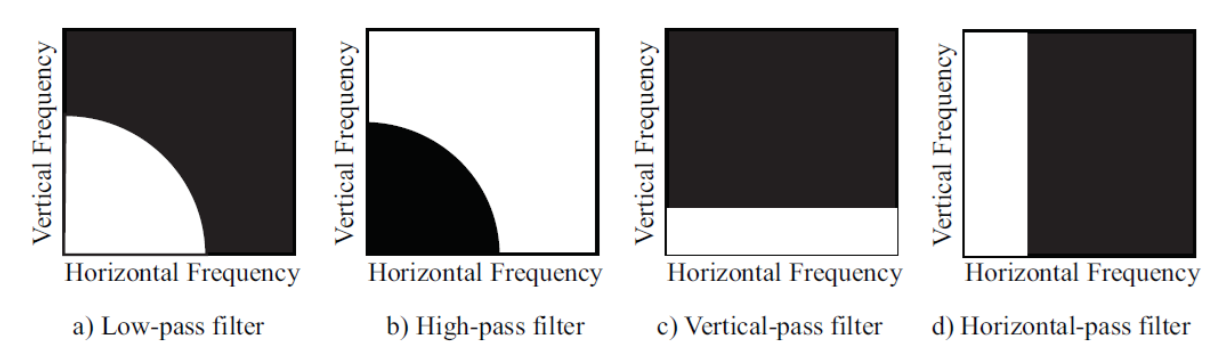

**ILL. 2.1*** 2-D image filters*

ILL. 2.2 is an illustration of selective filtering. The input is a superposition of a periodic function in the vertical direction (y), and a periodic function in the horizontal direction (x). The system is an horizontal low-pass filter. The transfer function shown in ILL. 2.1 (d) is an example of such. As a result, the output only contains the vertical periodic function. 

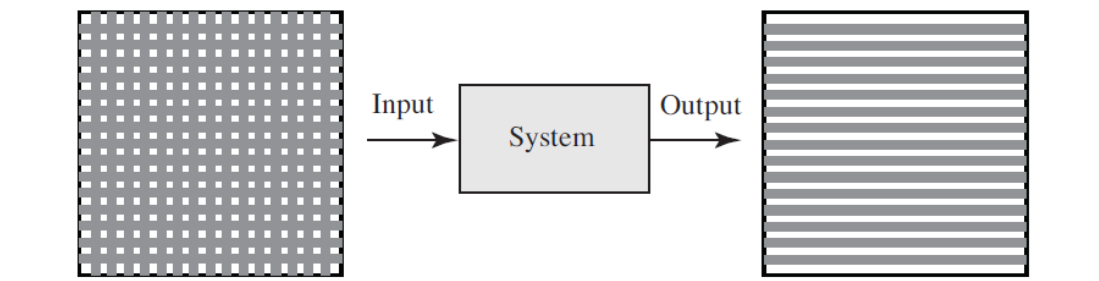

**ILL 2.1*** 2-D filter illustration of horizontal low pass filtering*

In this section, we will take a look at the transfer functions we introduced in Lecture 2. 

### 2.1 Transfer functions of additive 2D filters

We have mentioned some of the most popular additive 2-D filters. Specifically,

- Nearest-neighbor uniform averaging 

- Boxcar filter

- Horizontal/vertical uniform averaging

- Non-uniform averaging

Example 2.1 and 2.2 are examples of a boxcar filter and a 3x3 non-uniform averaging filter. 

***Example 2.1 ***

2-D transfer function of Boxcar filter. 

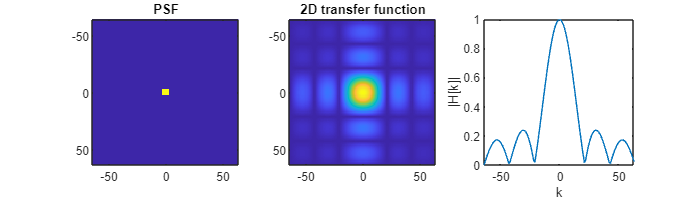

n = 128;
n_tap = 6;
h = ones(n_tap)./(n_tap.^2); 
pad_size = round((n-length(h))/2);
h_pad = padarray(h,[pad_size,pad_size],'both'); % PSF
h_hat=fftshift(fft2(fftshift(h_pad))); % transfer function
figure;
subplot(131);
imagesc(-n/2:n/2-1,-n/2:n/2-1,h_pad);
axis image;axis equal;
title('PSF');
subplot(132);
imagesc(-n/2:n/2-1,-n/2:n/2-1,abs(h_hat));
axis image;axis equal;
title('2D transfer function');
subplot(133);
plot((-n/2:n/2-1),abs(h_hat(round(n/2),:)));
xlabel('k');ylabel('|H[k]|');
set(gcf,'Position',[100 100 700 200]);

***Example 2.2 ***

2D transfer function of a non-uniform filter.

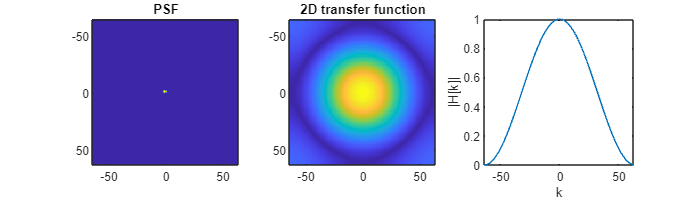

n = 128;
h = zeros(n);
h(n/2-1:n/2+1,n/2-1:n/2+1)=[0.05,0.15,0.05;0.15,0.2,0.15;0.05,0.15,0.05]; % PSF
h_hat=fftshift(fft2(fftshift(h))); % transfer function
figure;
subplot(131);
imagesc(-n/2:n/2-1,-n/2:n/2-1,h);
axis image;axis equal;
title('PSF');
subplot(132);
imagesc(-n/2:n/2-1,-n/2:n/2-1,abs(h_hat));
title('2D transfer function');
axis image;axis equal;
subplot(133);
plot(-n/2:n/2-1,abs(h_hat(round(n/2),:)));
xlabel('k');ylabel('|H[k]|');
set(gcf,'Position',[100 100 700 200]);

***Example 2.3 ***

Circ function PSF.

A system with an impulse response function in the form of a uniform circular function of radius $\rho_s$,


$$h\left(x,y\right)=\frac{1}{\pi {\left(\rho_s \right)}^2 }\textrm{circ}\left(\frac{x}{\rho_s },\frac{y}{\rho_s }\right),$$


Transfer function: $H\left(k_x ,k_y \right)=\frac{2J_1 \left(\rho_s k_{\rho } \right)}{\rho_s k_s },\;\;\;\;\;k_{\rho } =\sqrt{k_x^2 +k_y^2 }$ 

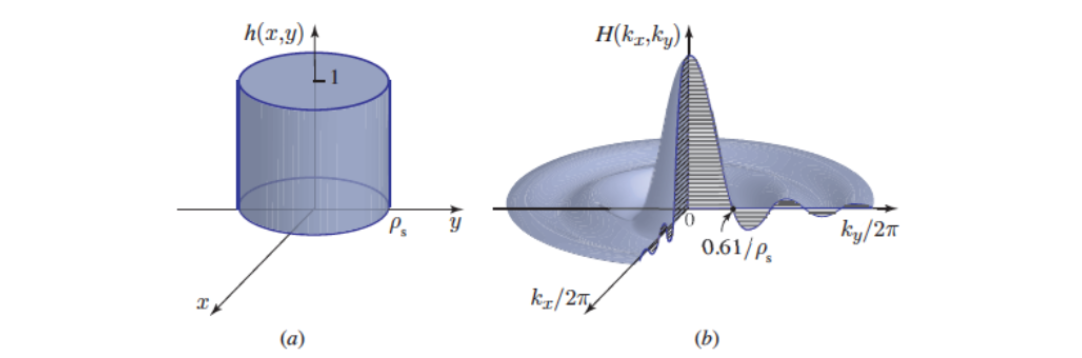

**ILL. 2.3*** (a) PSF is a circ function with radius *$\rho_s$*. (b) Transfer function has its first zero at a spatial frequency *$\frac{k_{\rho } }{2\pi }=\frac{0\ldotp 61}{\rho_s }\;\frac{\textrm{cycles}}{\textrm{mm}}$

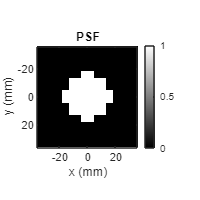

n_h = 8; % kernel half-size pixel number
xh = linspace(-2,2,2*n_h);
yh = linspace(-2,2,2*n_h);
dx = xh(2)-xh(1); % pixel size
[Xh,Yh]=ndgrid(xh,yh);
rho_s = 1; % PSF radius
Kernel=zeros(2*n_h);
Kernel(Xh.^2+Yh.^2<rho_s^2) = 1; % circle with radius of rho_s

figure;
imagesc(x,y, Kernel)
axis image;axis equal;
xlabel('x (mm)'),ylabel('y (mm)');
set(gcf,'Position',[100 100 200 200]);
colormap('gray');colorbar;
title('PSF')

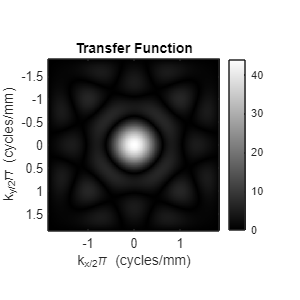

% input image
InputImg=double(imread('cameraman.tif'));
[m,n]=size(InputImg); % size of the input image
x = (-m/2:m/2-1)*dx; % coordinates of the image
y = (-n/2:n/2-1)*dx;
% PSF and transfer function
kx = (-m/2:m/2-1)/m/dx;% spatial frequency coordinates
ky = (-n/2:n/2-1)/n/dx;
H = padarray(Kernel,[m/2,n/2],0); % PSF
H_hat = fftshift(fft2(fftshift(H))); % transfer function

figure;
imagesc(kx,ky,abs(H_hat));
axis image;axis equal;
xlabel('k_x/2\pi (cycles/mm)'),ylabel('k_y/2\pi (cycles/mm)');
set(gcf,'Position',[100 100 300 300]);
colormap('gray');colorbar;
title('Transfer Function')

You can see here the Transfer function has its first zero at a spatial frequency $\frac{k_{\rho } }{2\pi }=0\ldotp 61\frac{\textrm{cycles}}{\textrm{mm}}$

### **2.2 Denoising using low-pass filter**

Noise often contains high-frequency components. This is especially true  for electronic noise or environmental noise, which tends to add  high-frequency 'hiss' or 'static' to the signal. By using a low-pass filter, high-frequency noise is attenuated, which  means it's reduced in amplitude, making it less prominent in the output signal. This results in a cleaner or smoother signal. Low-pass filters are relatively easy to implement in both analog and digital forms, making them a convenient choice for many applications.

However, it is important to choose the right cutoff frequency for the low-pass filter. If the cutoff frequency is too low, it might also filter out important parts of the signal. If it's too high, it might not effectively remove the noise. This balance is crucial for effective noise reduction.

***Example 2.4***

Adjust the lowpass filter for denoising.

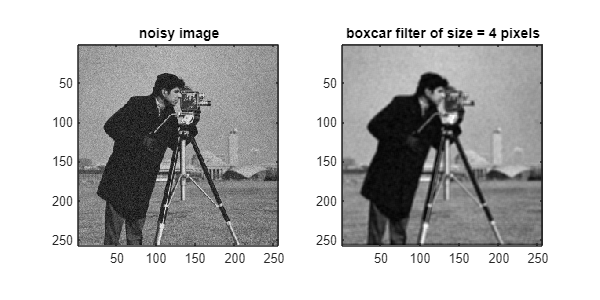

OriginalImg = double(imread('cameraman.tif'));
noise_level = 5e-2; % noise level
NoisyImg = OriginalImg+ noise_level*max(OriginalImg(:))*randn(size(OriginalImg));
% filter
n_tap =4;
h = ones(n_tap)./(n_tap.^2); 
% filtered image
FltdImg=conv2(NoisyImg, h,'same');
figure;
subplot(121)
imagesc(NoisyImg);
axis image;axis equal;
title('noisy image')
colormap('gray');
subplot(122)
imagesc(FltdImg);
axis image;axis equal;
title(['boxcar filter of size = ',num2str(n_tap), ' pixels']);
colormap('gray');
set(gcf,'Position',[100 100 600 300]);

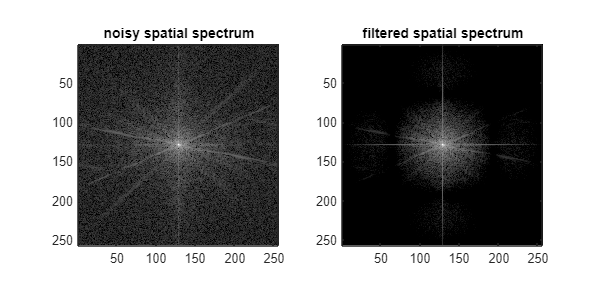

% spatial freqeuncy domain
figure;
subplot(121)
imagesc(abs(fftshift(fft2(fftshift(NoisyImg)))));
axis image;axis equal;
title('noisy spatial spectrum')
colormap('gray');
set(gca,'ColorScale','log') % plot log scale
subplot(122)
imagesc(abs(fftshift(fft2(fftshift(FltdImg)))));
axis image;axis equal;
title('filtered spatial spectrum')
colormap('gray');
set(gca,'ColorScale','log') % plot log scale
set(gcf,'Position',[100 100 600 300]);

Which filtered image looks the best? Can you come up with a metric to quantitatively compare their performances?

### 2.3 Subtractive 2D filters

Some of the most commonly used subtractive filters are:

- The horizontal difference operation

- The vertical difference operation

- Second order horizontal

- Second order two dimensional (Laplacian)

Example 2.5 and 2.6 are the examples of first order horizontal difference filter and a Laplacian filter. 

***Example 2.5***

Transfer function of horizontal difference filter.

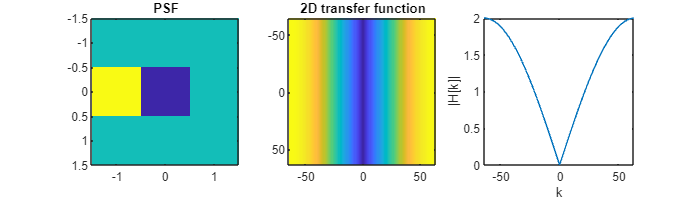

n = 128;
h_pad = zeros(n);
h_pad(n/2,n/2-1:n/2+1) = [1,-1,0];
h_hat = fftshift(fft2(fftshift(h_pad)));
figure;
subplot(131);
imagesc(-1:1,-1:1,h_pad(n/2-1:n/2+1,n/2-1:n/2+1));
axis image;axis equal;
title('PSF');
subplot(132);
imagesc(-n/2:n/2-1,-n/2:n/2-1,abs(h_hat));
axis image;axis equal;
title('2D transfer function');
subplot(133);
plot(-n/2:n/2-1,abs(h_hat(round(n/2),:)));
xlabel('k');ylabel('|H[k]|');
set(gcf,'Position',[100 100 700 200]);

***Example 2.5***

Laplacian (2nd order difference) filter.

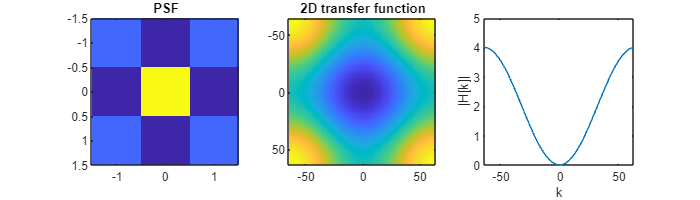

n = 128;
h_pad = zeros(n);
h_pad(n/2-1:n/2+1,n/2-1:n/2+1) = [0,-1,0;-1,4,-1;0,-1,0];
h_hat=fftshift(fft2(fftshift(h_pad)));
figure;
subplot(131);
imagesc(-1:1,-1:1,h_pad(n/2-1:n/2+1,n/2-1:n/2+1));
axis image;axis equal;
title('PSF');
subplot(132);
imagesc(-n/2:n/2-1,-n/2:n/2-1,abs(h_hat));
axis image;axis equal;
title('2D transfer function');
subplot(133);
plot(-n/2:n/2-1,abs(h_hat(round(n/2),:)));
xlabel('k');ylabel('|H[k]|');
set(gcf,'Position',[0 100 700 200]);

### **2.4 Edge detection using difference filtering**

Edges in an image are a form of high-frequency component. Difference  filters are sensitive to high-frequency changes, making them well-suited for detecting these rapid transitions. Difference filters can be designed to be sensitive to changes in specific directions (horizontal, vertical, diagonal), allowing for the  detection of edges oriented in different ways. Difference filters also have some limitations. They can be sensitive to noise, as noise often also manifest as rapid intensity changes. To address this, it's common to apply a smoothing filter (like a Gaussian filter)  before using a difference filter, helping to reduce the impact of noise on edge detection.

***Example 2.7 ***

Edge detection and enhancement using difference filtering.

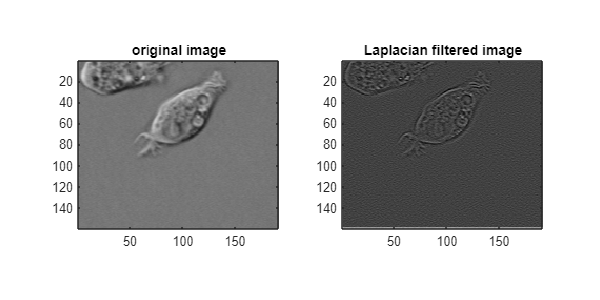

InputImg = double(imread('cell.tif'));
h = [0,-1,0;-1,4,-1;0,-1,0];
HfImg=conv2(InputImg, h,'same');

figure;
subplot(121)
image(InputImg);
axis image;axis equal;
title('original image')
colormap('gray');
subplot(122)
imagesc(HfImg);
axis image;axis equal;
title('Laplacian filtered image');
colormap('gray');
set(gcf,'Position',[100 100 600 300]);

You may find the filtered image quite familiar. Actually, a special type of microscope called differential interference contrast (DIC) microscope can directly generate images similar to this one. The interested readers can search DIC modality and see how using interference can achieve high-pass filtering. 

Now if we change the kernel a little bit, $\left\lbrack \begin{array}{ccc}
0 & -1 & 0\\
-1 & 4 & -1\\
0 & -1 & 0
\end{array}\right\rbrack \longrightarrow \left\lbrack \begin{array}{ccc}
0 & -1 & 0\\
-1 & 5 & -1\\
0 & -1 & 0
\end{array}\right\rbrack$, we get an edge enhancement filter.

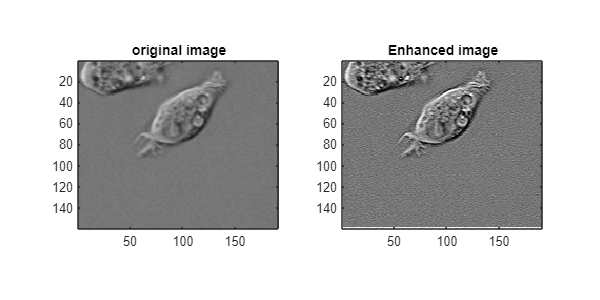

InputImg = double(imread('cell.tif'));
h2 = [0,-1,0;-1,5,-1;0,-1,0];
EnhImg=conv2(InputImg, h2,'same');

figure;
subplot(121)
image(InputImg);
axis image;axis equal;
title('original image')
colormap('gray');
subplot(122)
image(EnhImg);
axis image;axis equal;
title('Enhanced image');
colormap('gray');
set(gcf,'Position',[100 100 600 300]);

Can you explain why?